# 서보모터 제어 시스템

## 1. 설계 목적

- Servo plant model을 얻는다.

- 모터의 위치제어와 각속도를 조절할 수 있는 제어기를 설계한다.

- Simulink를 통해 Servo plant를 구성하고, 구형파를 입력했을 때 결과를 구하고 디자인 한다.

## 2. 설계 제한

### A. root locus method

#### (1) 경제적 조건

- 모터에 인가되는 증폭기의 용량을 가능한 적게 하여 비용을 낮게 한다.(파라미터를 최대한 작게 한다.)

#### (2) 생산성과 내구성

- 가능한 빠른 시간 내에 목표치(스텝 입력)에 도달해야 한다.

- 모터를 가능한 오래 사용할 수 있는 제어기를 설계해야 한다.(oscillation이 가능한 적게, 즉 settling time이 적게 설계한다.)

#### (3) 기타

- 폐루프의 dominant pole의 damping ratio는 0.3-0.8사이의 값이어야 하며 settling time은 1/40 sec보다 작아야한다. 

### B. Frequency domain method

#### (1) 생산성 제한조건

- 가능한 빠른 시간 내에 목표치(스텝 입력)에 도달해야 한다.

- ramp input에 대해 가능한 오차가 적어야 한다.

#### (2) 안정성

- 가능한 phase margin이 30도 이상 커야한다.

## 3. 설계과정

Simulink를 이용해 구성한 주어진 Servo plant 블럭선도는 아래 그림과 같다. 계단 입력은 10으로 설정했다.

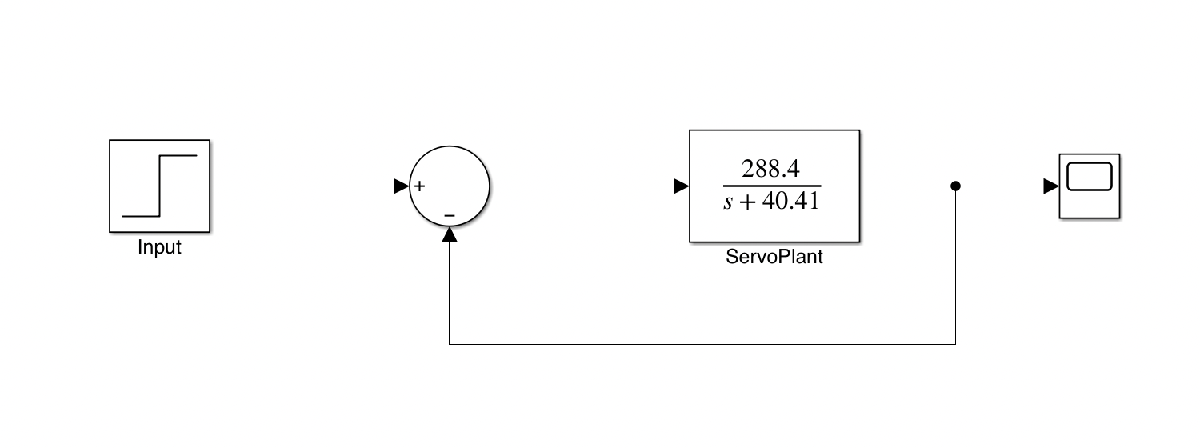

그리고 스코프에 출력되는 파형은 다음과 같다.

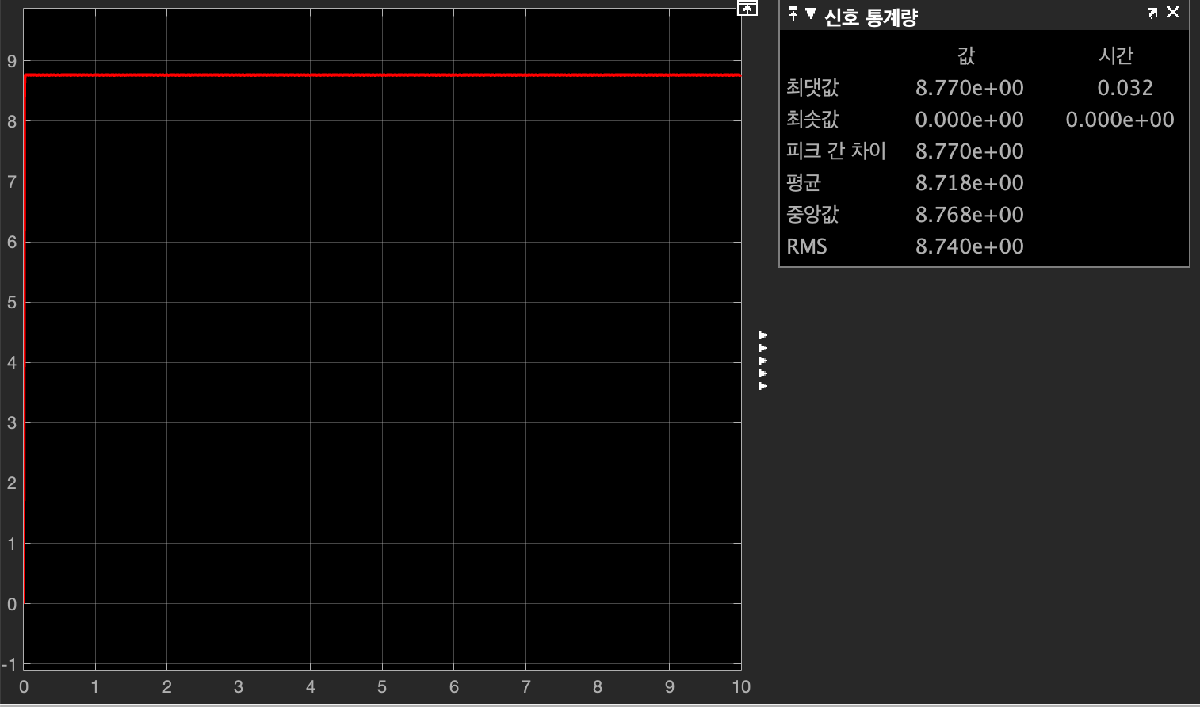

응답 시간은 굉장히 빨랐지만 입력한 목표치인 10에 못 미치는 것을 볼 수 있습니다.

### A. root locus method

PID 제어기를 장착하기 전 servo plant model의 root locus와 계단 입력은 다음과 같습니다.

p = [288.4];
q = [1 40.41];
gs = tf(p, q);
sys = feedback(gs, [1])

sys =
 
    288.4
  ---------
  s + 328.8
 
연속시간 전달 함수입니다.



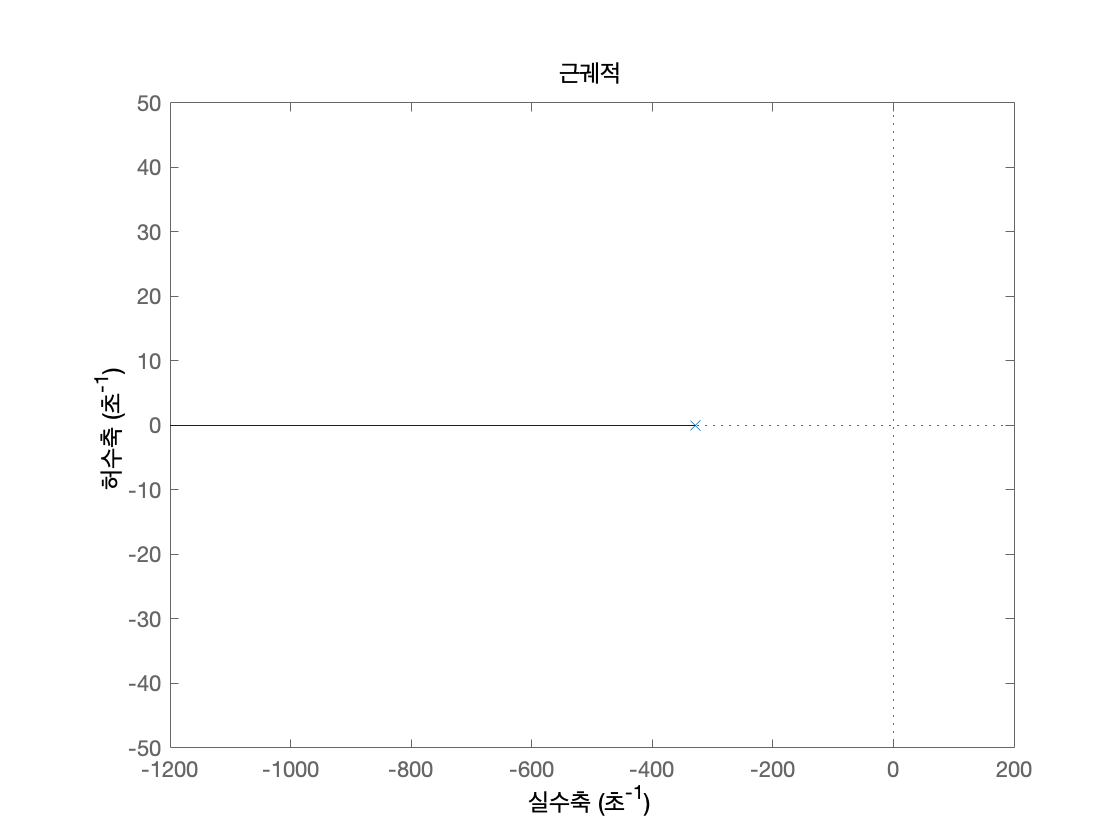

rlocus(sys)

극점이 좌반면에 있긴하지만 위에서 볼 수 있드시 목표값에 도달하지 못 하는 것을 볼 수 있었습니다. 자료조사와 회의를 통해 주어진 설계 제한을 만족하기 위해 적절한 제어기를 찾기로 결정했습니다.

### A-1. P 제어기를 사용할 경우

P 제어기만 사용하면 극점의 변화가 없어 극점의 변화가 없습니다. 그러므로 P 제어기만 사용하는 것은 좋은 방법이 아닙니다.

### A-2. PI 제어기를 사용할 경우

PI 제어기의 수식은 아래식과 같습니다.


$$K_P +\frac{K_I }{s}=\frac{sK_P +K_I }{s}$$


그리고 전달함수 $G\left(s\right)$는 아래 수식입니다.


$$G\left(s\right)=\frac{288\ldotp 4\left({s\;K}_P +K_I \right)}{s\left(s+40\ldotp 41\right)}$$


$K_p$와 $K_I$를 1로 가정하고 근궤적과 계단입력 반응 그리겠습니다.

KP = 1;
KI = 1;
p = 288.4 * [KP KI];
q = [1 40.41 0];
gs = tf(p, q);
sys = feedback(gs, [1])

sys =
 
     288.4 s + 288.4
  ---------------------
  s^2 + 328.8 s + 288.4
 
연속시간 전달 함수입니다.



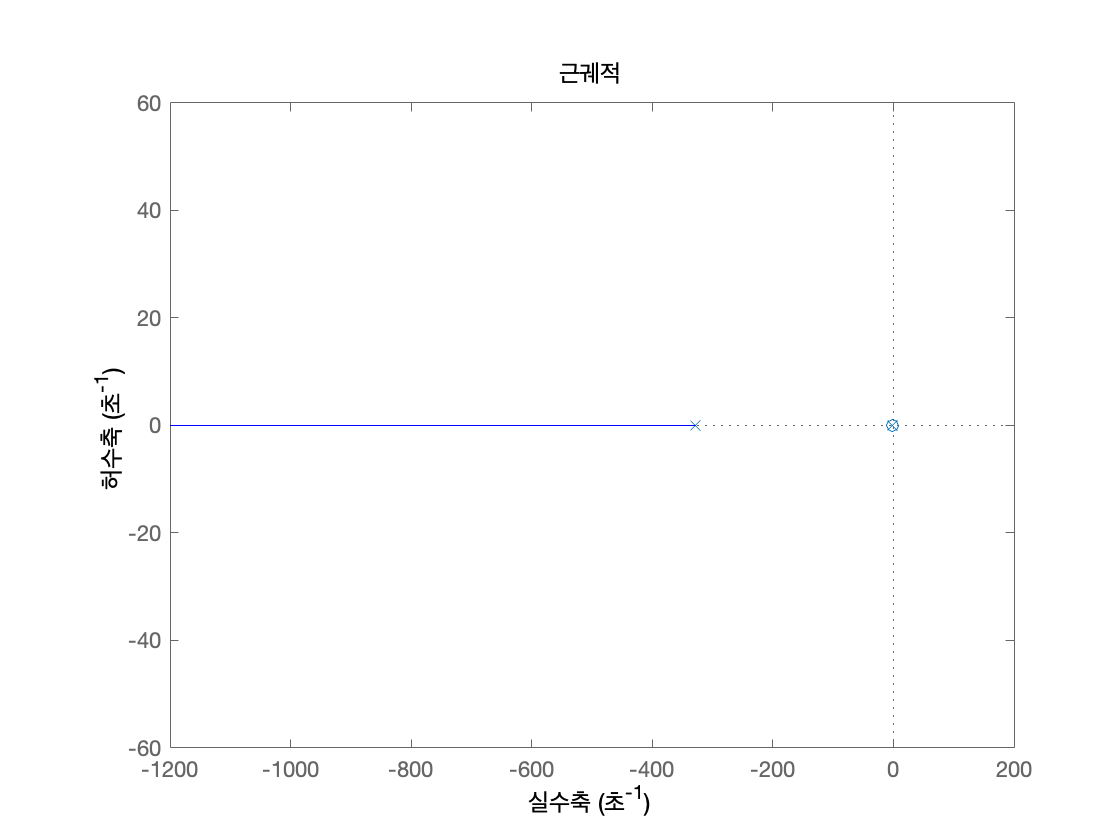

rlocus(sys)

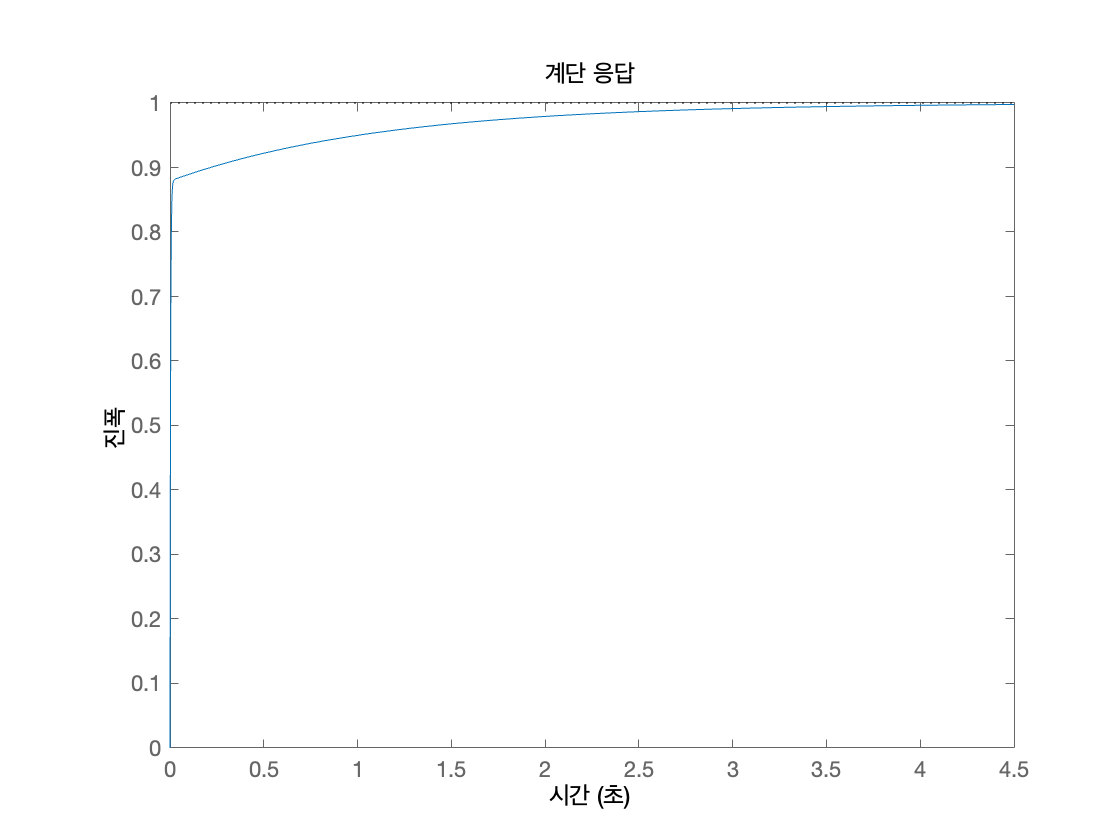

step(sys)

stepinfo(sys)

ans = 다음 필드를 포함한 struct :
        RiseTime: 0.2152
    SettlingTime: 2.0456
     SettlingMin: 0.9000
     SettlingMax: 0.9982
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9982
        PeakTime: 4.7940


근궤적도를 보면 극점은 좌반면에 있고 영점은 원점에 있으므로 안정적인 시스템입니다. 그리고 계단 입력을 보면 SettlingTime이 늦긴 하지만 목표값에 도달한 것을 볼 수 있습니다. 그러므로 PI 제어기가 적절한 제어기로 보입니다.

### A-3. PD 제어기를 사용할 경우

PD 제어기 수식은 아래와 같습니다.


$$K_P +s\;K_D$$


그리고 전달함수 $G\left(s\right)$수식입니다.


$$G\left(s\right)=\frac{288\ldotp 4\left(K_P +{s\;K}_D \right)}{s+40\ldotp 41}$$


마찬가지로 $K_P$와 $K_D$을 1로 두고 근궤적과 계단입력 반응을 그렸습니다.

KP = 1;
KD = 1;
p = 288.4 * [KD KP];
q = [1 40.41];
gs = tf(p, q);
sys = feedback(gs, [1])

sys =
 
  288.4 s + 288.4
  ---------------
  289.4 s + 328.8
 
연속시간 전달 함수입니다.



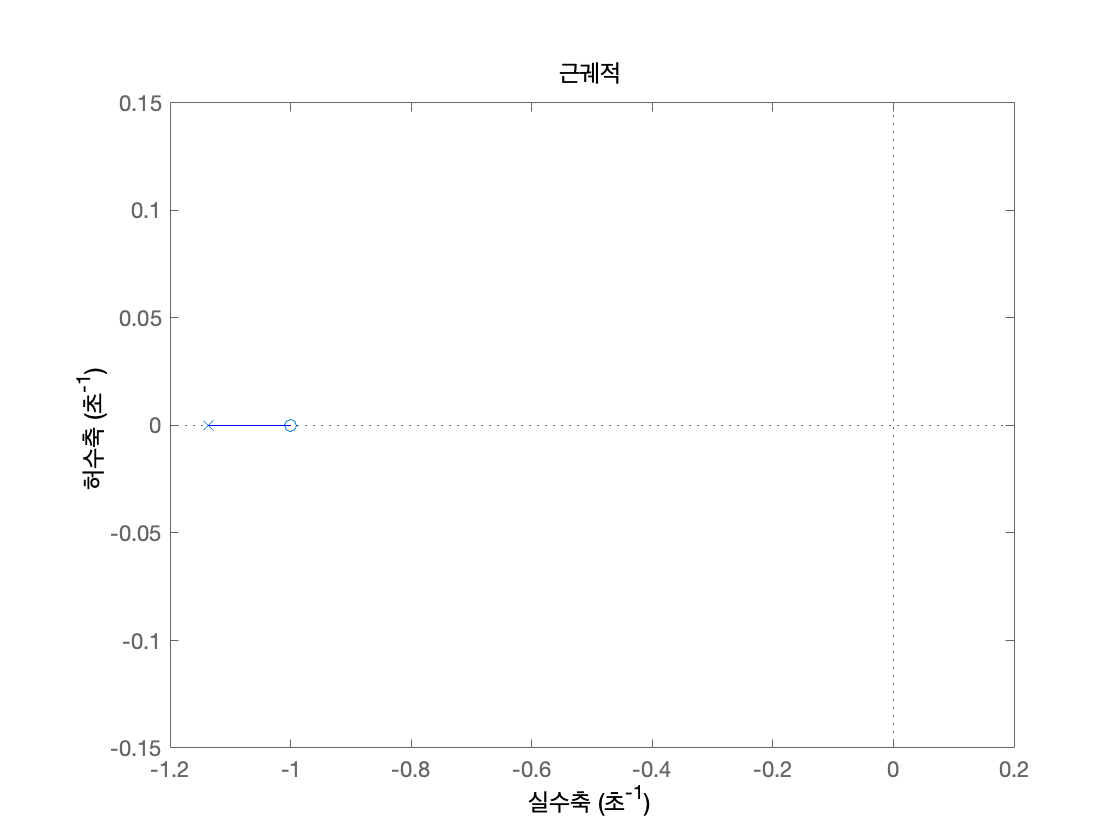

rlocus(sys)

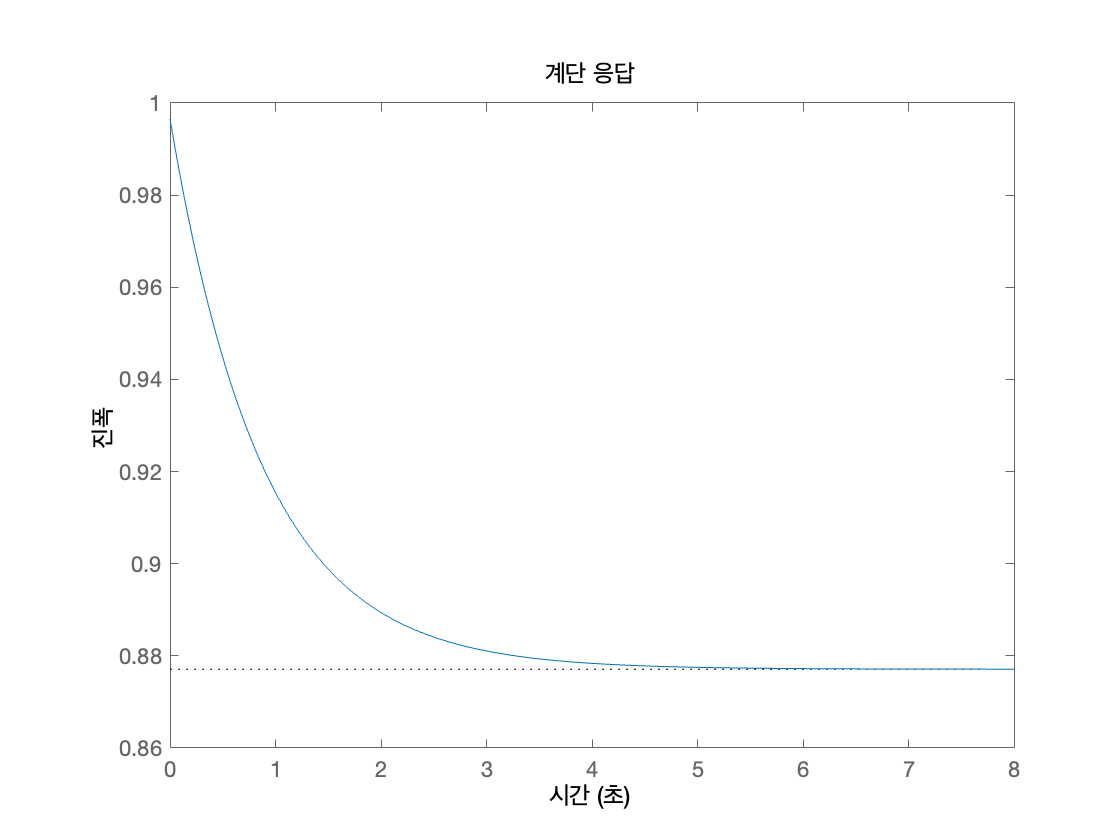

step(sys)

stepinfo(sys)

ans = 다음 필드를 포함한 struct :
        RiseTime: 1.9337
    SettlingTime: 3.4432
     SettlingMin: 0.8771
     SettlingMax: 0.8885
       Overshoot: 13.6178
      Undershoot: 0
            Peak: 0.9965
        PeakTime: 0


damp(sys)

                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -1.14e+00     1.00e+00       1.14e+00       8.80e-01  


근궤적도를 보면 극점과 영점 모두 좌반면에 있어 안정적인 시스템입니다. 하지만 계단입력 반응을 보았을 때 오히려 응답이 작아지고 있습니다. 계단 응답 그래프를 보았을 때 PD 제어기는 적절하지 않아 보입니다.

### A-4. PID 제어기를 사용할 경우

PID 제어기 수식은 아래와 같습니다.


$$K_P +\frac{K_I }{s}+{s\;K}_D =\frac{s^2 \;K_D +K_P +K_I }{s}$$


그리고 전달함수 $G\left(s\right)$수식입니다.


$$G\left(s\right)=\frac{288\ldotp 4\left(s^2 \;K_D +K_P +K_I \right)}{s\left(s+40\ldotp 41\right)}$$


PID 제어기의 근궤적과 계단 응답을 위한 코드입니다.

KP = 1;
KI = 1;
KD = 1;
p = 288.4 * [KP KI KD];
q = [1 40.41 0];
gs = tf(p, q);
sys = feedback(gs, [1])

sys =
 
  288.4 s^2 + 288.4 s + 288.4
  ---------------------------
  289.4 s^2 + 328.8 s + 288.4
 
연속시간 전달 함수입니다.



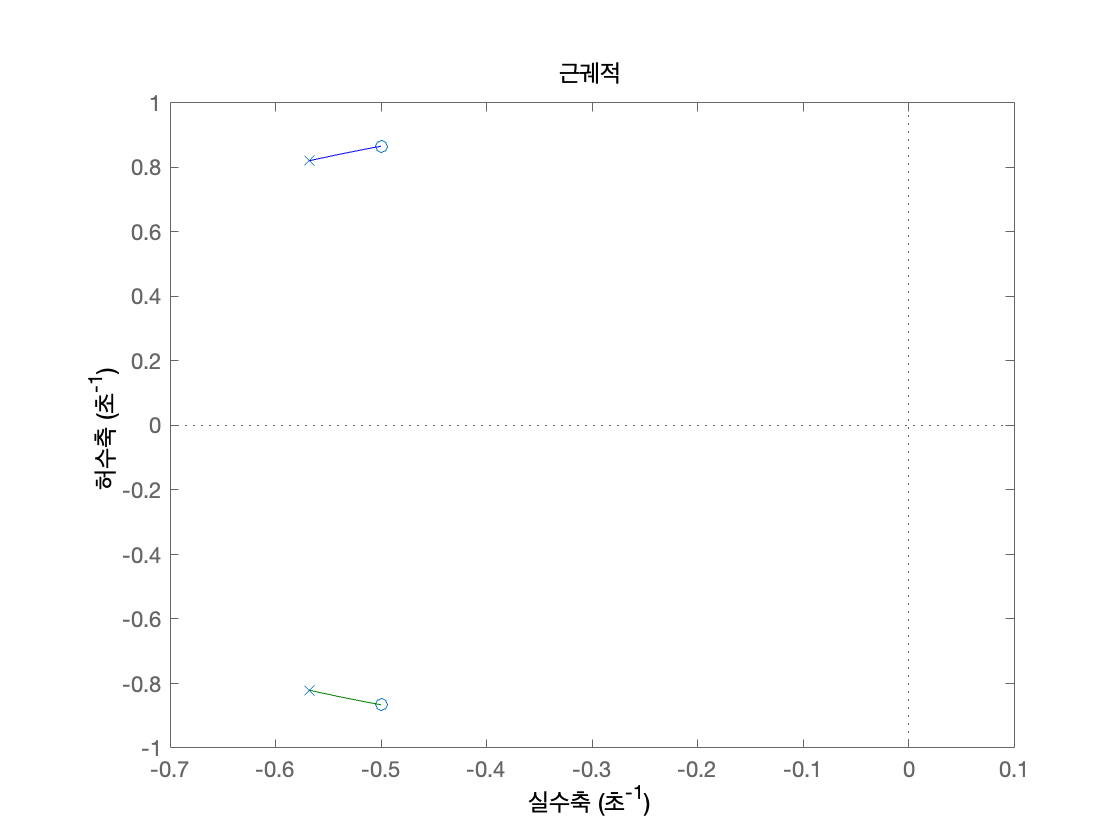

rlocus(sys)

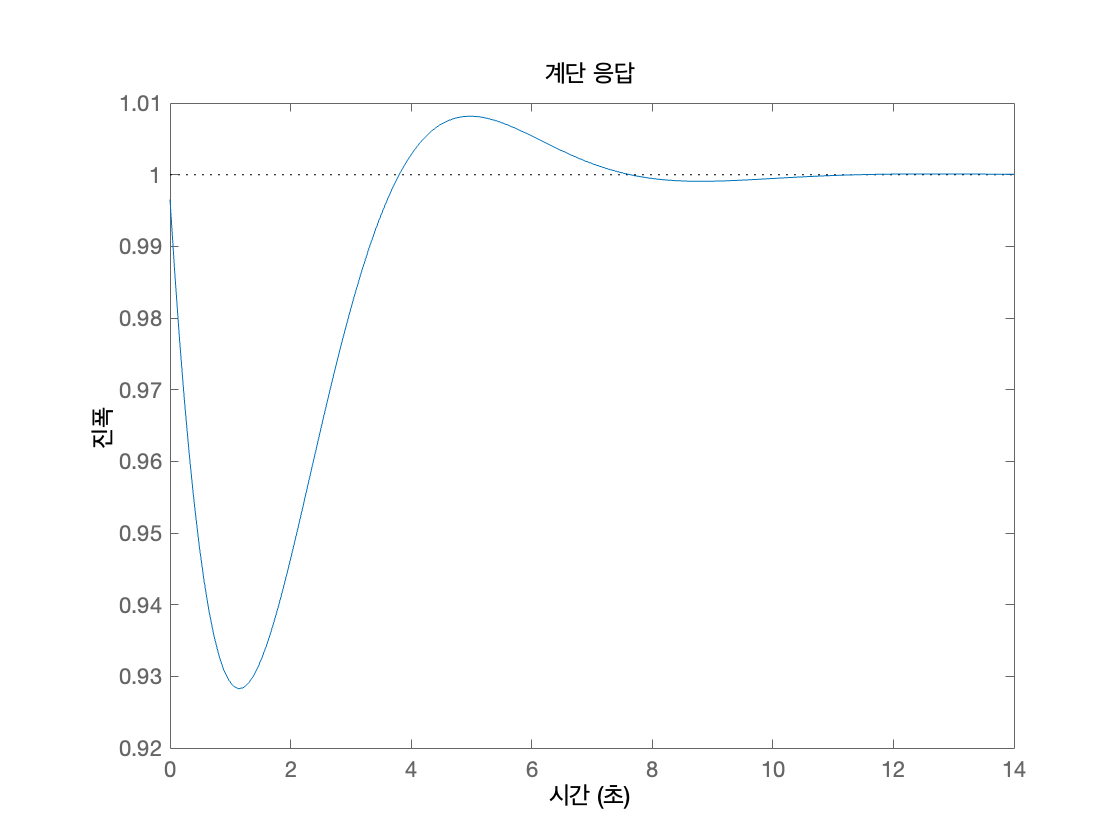

step(sys)

stepinfo(sys)

ans = 다음 필드를 포함한 struct :
        RiseTime: 0.1563
    SettlingTime: 7.0388
     SettlingMin: 0.9991
     SettlingMax: 1.0082
       Overshoot: 0.8151
      Undershoot: 0
            Peak: 1.0082
        PeakTime: 4.9449


damp(sys)

                                                                   
          극점                 감쇠             주파수            시정수     
                                       (rad/seconds)    (seconds)  
                                                                   
 -5.68e-01 + 8.21e-01i     5.69e-01       9.98e-01       1.76e+00  
 -5.68e-01 - 8.21e-01i     5.69e-01       9.98e-01       1.76e+00  


근궤적 그래프를 보았을 때 극점과 영점이 좌반면에 있고 발산하지 않아 안정한 시스템입니다. 하지만 계단 입력을 보면 응답시간이 너무 늦고 심지어 오버슈팅까지 있습니다. 설계 조건을 만족하지 않으므로 PID 제어기는 옳지 않습니다.

### A-5. 적절한 파라미터 찾기

PI 제어기가 서보 모터를 제어하기에 가장 적절하다는 것을 알았으니 이제 설계조건을 최대한 만족하는 $K_P$와 $K_I$를 찾겠습니다. 먼저 설계조건에서 $K_P$와 $K_I$는 작을 수록 좋다 했으므로 줄여보겠습니다.

KP = 1,KI = 1


sys =
 
     288.4 s + 288.4
  ---------------------
  s^2 + 328.8 s + 288.4
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.2152
    SettlingTime: 2.0456
     SettlingMin: 0.9000
     SettlingMax: 0.9982
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9982
        PeakTime: 4.7940


KP = 0.9,KI = 0.9


sys =
 
    259.6 s + 259.6
  -------------------
  s^2 + 300 s + 259.6
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.3246
    SettlingTime: 2.1797
     SettlingMin: 0.9000
     SettlingMax: 0.9963
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9963
        PeakTime: 4.1198


KP = 0.8,KI = 0.8


sys =
 
     230.7 s + 230.7
  ---------------------
  s^2 + 271.1 s + 230.7
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.4494
    SettlingTime: 2.3352
     SettlingMin: 0.9000
     SettlingMax: 0.9985
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9985
        PeakTime: 5.4043


KP = 0.7,KI = 0.7


sys =
 
     201.9 s + 201.9
  ---------------------
  s^2 + 242.3 s + 201.9
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.5945
    SettlingTime: 2.5200
     SettlingMin: 0.9000
     SettlingMax: 0.9987
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9987
        PeakTime: 5.7672


KP = 0.6,KI = 0.6


sys =
 
      173 s + 173
  -------------------
  s^2 + 213.4 s + 173
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.7681
    SettlingTime: 2.7464
     SettlingMin: 0.9000
     SettlingMax: 0.9968
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9968
        PeakTime: 4.9851


KP = 0.5,KI = 0.5


sys =
 
     144.2 s + 144.2
  ---------------------
  s^2 + 184.6 s + 144.2
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.9838
    SettlingTime: 3.0363
     SettlingMin: 0.9000
     SettlingMax: 0.9996
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9996
        PeakTime: 7.9459


KP = 0.4,KI = 0.4


sys =
 
     115.4 s + 115.4
  ---------------------
  s^2 + 155.8 s + 115.4
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 1.2680
    SettlingTime: 3.4318
     SettlingMin: 0.9000
     SettlingMax: 0.9971
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9971
        PeakTime: 6.0237


KP = 0.3,KI = 0.3


sys =
 
     86.52 s + 86.52
  ---------------------
  s^2 + 126.9 s + 86.52
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 1.6793
    SettlingTime: 4.0290
     SettlingMin: 0.9000
     SettlingMax: 0.9976
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9976
        PeakTime: 7.1125


KP = 0.2,KI = 0.2


sys =
 
     57.68 s + 57.68
  ---------------------
  s^2 + 98.09 s + 57.68
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 2.3868
    SettlingTime: 5.1092
     SettlingMin: 0.9000
     SettlingMax: 0.9997
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9997
        PeakTime: 12.1947


KP = 0.1,KI = 0.1


sys =
 
     28.84 s + 28.84
  ---------------------
  s^2 + 69.25 s + 28.84
 
연속시간 전달 함수입니다.



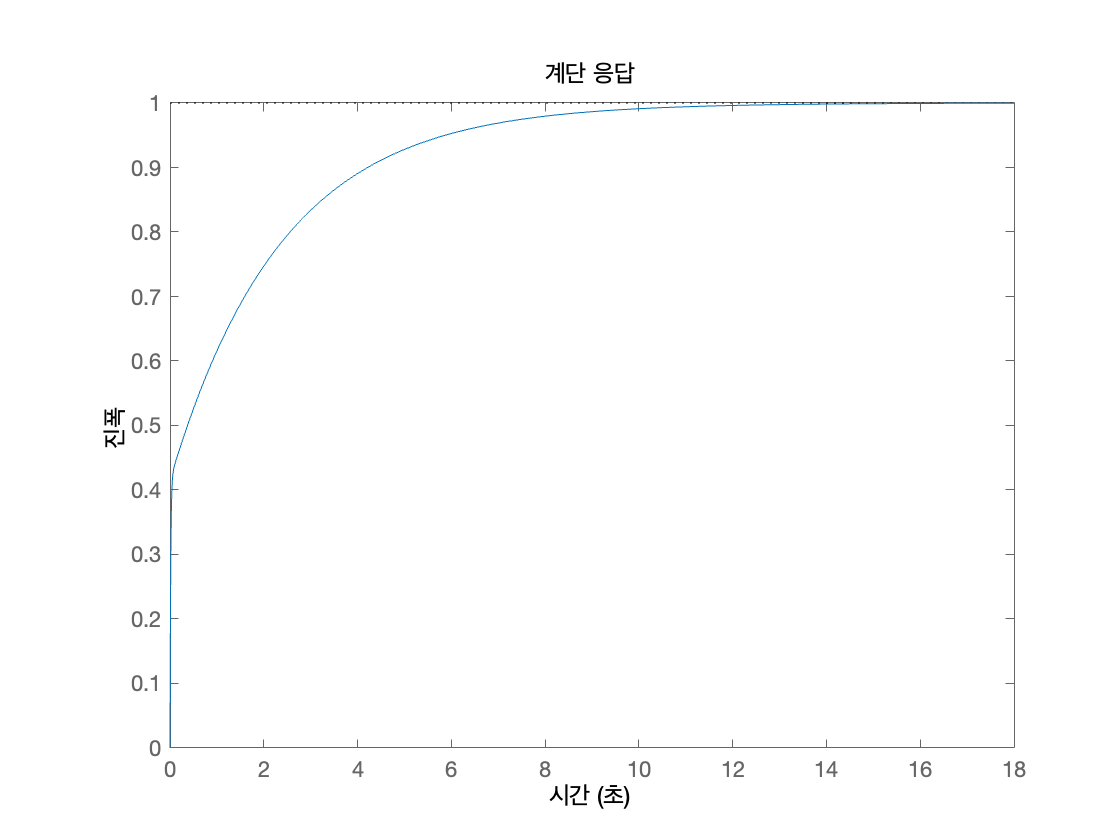

ans = 다음 필드를 포함한 struct :
        RiseTime: 4.2101
    SettlingTime: 8.0553
     SettlingMin: 0.9000
     SettlingMax: 0.9998
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9998
        PeakTime: 19.2674


KP = (linspace(1,0.1,10))';
KI = (linspace(1,0.1,10))';
para = [KP KI];
k = length(KP);

for i = 1:k
    p = 288.4 * [para(i,1) para(i,2)];
    q = [1 40.41 0];
    gs = tf(p, q);
    disp(['KP = ',num2str(para(i,1)),',','KI = ', num2str(para(i,2))])
    sys = feedback(gs, [1])
    rlocus(sys)
    step(sys)
    stepinfo(sys)
end

$K_P$와 $K_I$가 작아질 수록 RiseTime과 SettlingTime이 증가하는 것을 관찰할 수 있습니다. 그러므로 이번엔 파라미터를 늘려보겠습니다.

KP = 1,KI = 1


sys =
 
     288.4 s + 288.4
  ---------------------
  s^2 + 328.8 s + 288.4
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.2152
    SettlingTime: 2.0456
     SettlingMin: 0.9000
     SettlingMax: 0.9982
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9982
        PeakTime: 4.7940


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -8.79e-01     1.00e+00       8.79e-01       1.14e+00  
 -3.28e+02     1.00e+00       3.28e+02       3.05e-03  


KP = 2,KI = 2


sys =
 
     576.8 s + 576.8
  ---------------------
  s^2 + 617.2 s + 576.8
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.0051
    SettlingTime: NaN
     SettlingMin: 0.9006
     SettlingMax: 0.9387
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9387
        PeakTime: 0.0492


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.36e-01     1.00e+00       9.36e-01       1.07e+00  
 -6.16e+02     1.00e+00       6.16e+02       1.62e-03  


KP = 3,KI = 3


sys =
 
     865.2 s + 865.2
  ---------------------
  s^2 + 905.6 s + 865.2
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.0030
    SettlingTime: NaN
     SettlingMin: 0.9014
     SettlingMax: 0.9577
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9577
        PeakTime: 0.0341


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.56e-01     1.00e+00       9.56e-01       1.05e+00  
 -9.05e+02     1.00e+00       9.05e+02       1.11e-03  


KP = 4,KI = 4


sys =
 
     1154 s + 1154
  -------------------
  s^2 + 1194 s + 1154
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.0021
    SettlingTime: NaN
     SettlingMin: 0.9001
     SettlingMax: 0.9677
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9677
        PeakTime: 0.0258


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.67e-01     1.00e+00       9.67e-01       1.03e+00  
 -1.19e+03     1.00e+00       1.19e+03       8.38e-04  


KP = 5,KI = 5


sys =
 
     1442 s + 1442
  -------------------
  s^2 + 1482 s + 1442
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.0017
    SettlingTime: NaN
     SettlingMin: 0.9029
     SettlingMax: 0.9739
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9739
        PeakTime: 0.0208


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.73e-01     1.00e+00       9.73e-01       1.03e+00  
 -1.48e+03     1.00e+00       1.48e+03       6.75e-04  


KP = 6,KI = 6


sys =
 
     1730 s + 1730
  -------------------
  s^2 + 1771 s + 1730
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.0014
    SettlingTime: NaN
     SettlingMin: 0.9001
     SettlingMax: 0.9781
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9781
        PeakTime: 0.0174


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.78e-01     1.00e+00       9.78e-01       1.02e+00  
 -1.77e+03     1.00e+00       1.77e+03       5.65e-04  


KP = 7,KI = 7


sys =
 
     2019 s + 2019
  -------------------
  s^2 + 2059 s + 2019
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.0012
    SettlingTime: 0.0034
     SettlingMin: 0.9029
     SettlingMax: 0.9811
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9811
        PeakTime: 0.0150


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.81e-01     1.00e+00       9.81e-01       1.02e+00  
 -2.06e+03     1.00e+00       2.06e+03       4.86e-04  


KP = 8,KI = 8


sys =
 
     2307 s + 2307
  -------------------
  s^2 + 2348 s + 2307
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 0.0010
    SettlingTime: 0.0024
     SettlingMin: 0.9014
     SettlingMax: 0.9834
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9834
        PeakTime: 0.0131


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.83e-01     1.00e+00       9.83e-01       1.02e+00  
 -2.35e+03     1.00e+00       2.35e+03       4.26e-04  


KP = 9,KI = 9


sys =
 
     2596 s + 2596
  -------------------
  s^2 + 2636 s + 2596
 
연속시간 전달 함수입니다.



ans = 다음 필드를 포함한 struct :
        RiseTime: 8.8893e-04
    SettlingTime: 0.0020
     SettlingMin: 0.9031
     SettlingMax: 0.9852
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9852
        PeakTime: 0.0117


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.85e-01     1.00e+00       9.85e-01       1.02e+00  
 -2.64e+03     1.00e+00       2.64e+03       3.80e-04  


KP = 10,KI = 10


sys =
 
     2884 s + 2884
  -------------------
  s^2 + 2924 s + 2884
 
연속시간 전달 함수입니다.



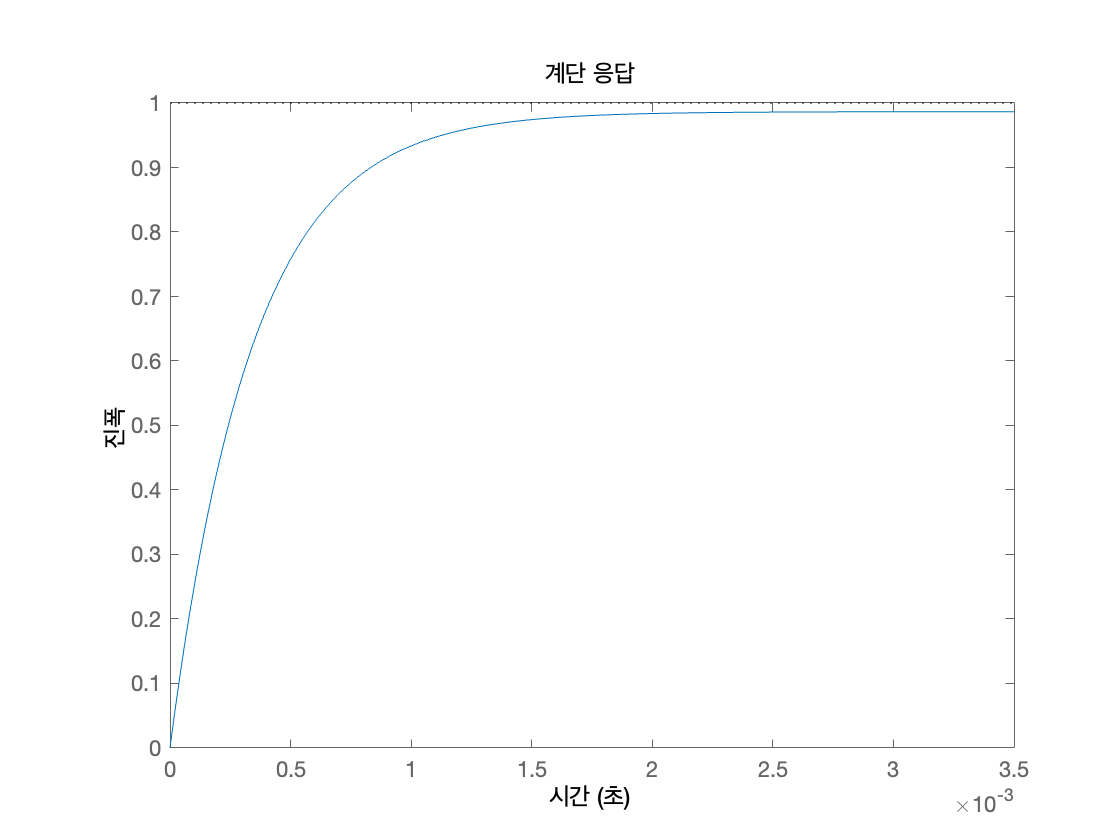

ans = 다음 필드를 포함한 struct :
        RiseTime: 7.9592e-04
    SettlingTime: 0.0017
     SettlingMin: 0.9006
     SettlingMax: 0.9866
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9866
        PeakTime: 0.0105


                                                       
    극점           감쇠             주파수            시정수     
                           (rad/seconds)    (seconds)  
                                                       
 -9.87e-01     1.00e+00       9.87e-01       1.01e+00  
 -2.92e+03     1.00e+00       2.92e+03       3.42e-04  


KP = (1:10)';
KI = (1:10)';
para = [KP KI];
k = length(KP);

for i = 1:k
    p = 288.4 * [para(i,1) para(i,2)];
    q = [1 40.41 0];
    gs = tf(p, q);
    disp(['KP = ',num2str(para(i,1)),',','KI = ', num2str(para(i,2))])
    sys = feedback(gs, [1])
    rlocus(sys)
    step(sys)
    stepinfo(sys)
    damp(sys)
end

결과 중에 SettlingTime이 Nan인 파라미터를 볼 수 있습니다. 이는 `sys`가 불안정하면 `Inf`인 `Peak`와 `PeakTime`을 제외하고 모든 계단 응답 특성이 `NaN`입니다.

모든 파라미터가 감쇠율은 모두 0이므로 조건을 충족하는 것을 합니다. 그러므로 $K_P =7,K_I =7$모든 조건을 만족하는 것을 알 수 있습니다.

## B. Frequency domain method

A의 결과를 토대로 PI제어기를 사용하면 목표치에 빠르게 도달할 수 있고 안정도도 뛰어났다. 그럼 ramp input과 bode plot 대해 관찰해 보자.

KP = 7;
KI = 7;
p = 288.4 * [KP KI];
q = [1 40.41 0];
gs = tf(p, q);
sys = feedback(gs, [1])

sys =
 
     2019 s + 2019
  -------------------
  s^2 + 2059 s + 2019
 
연속시간 전달 함수입니다.



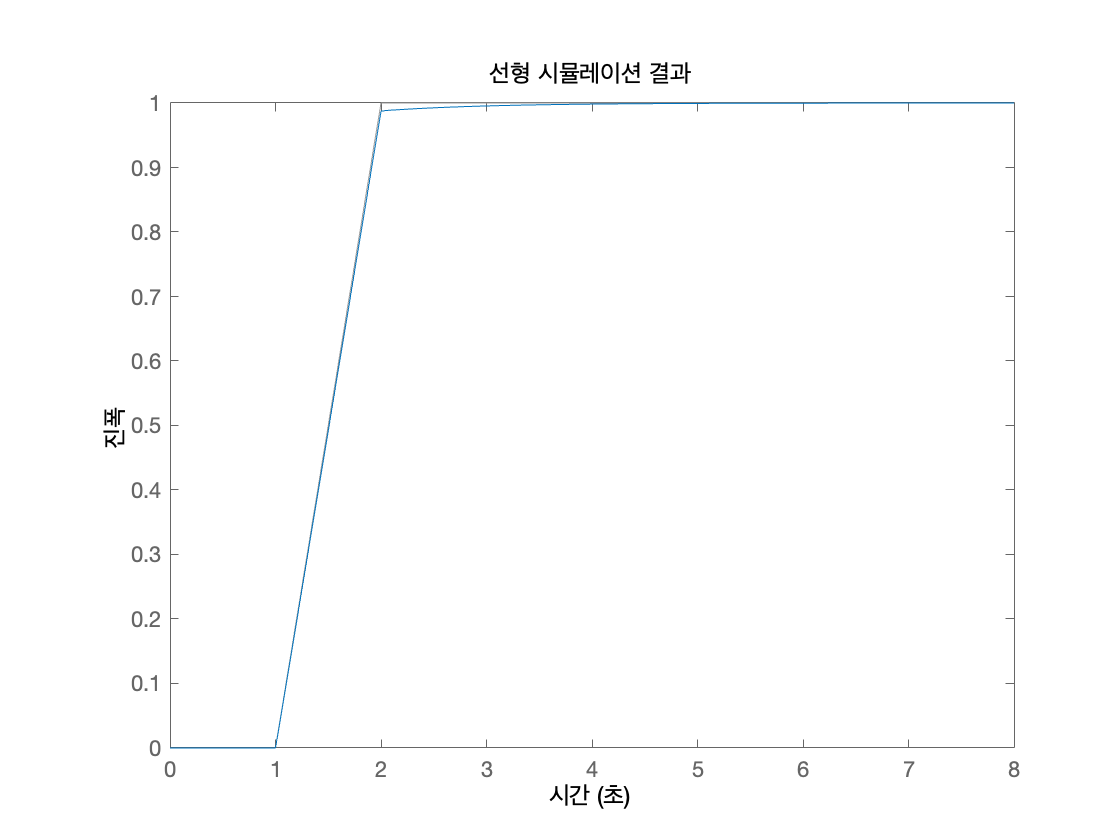

t = 0:0.04:8;
u = max(0,min(t-1,1));
lsim(sys,u,t)

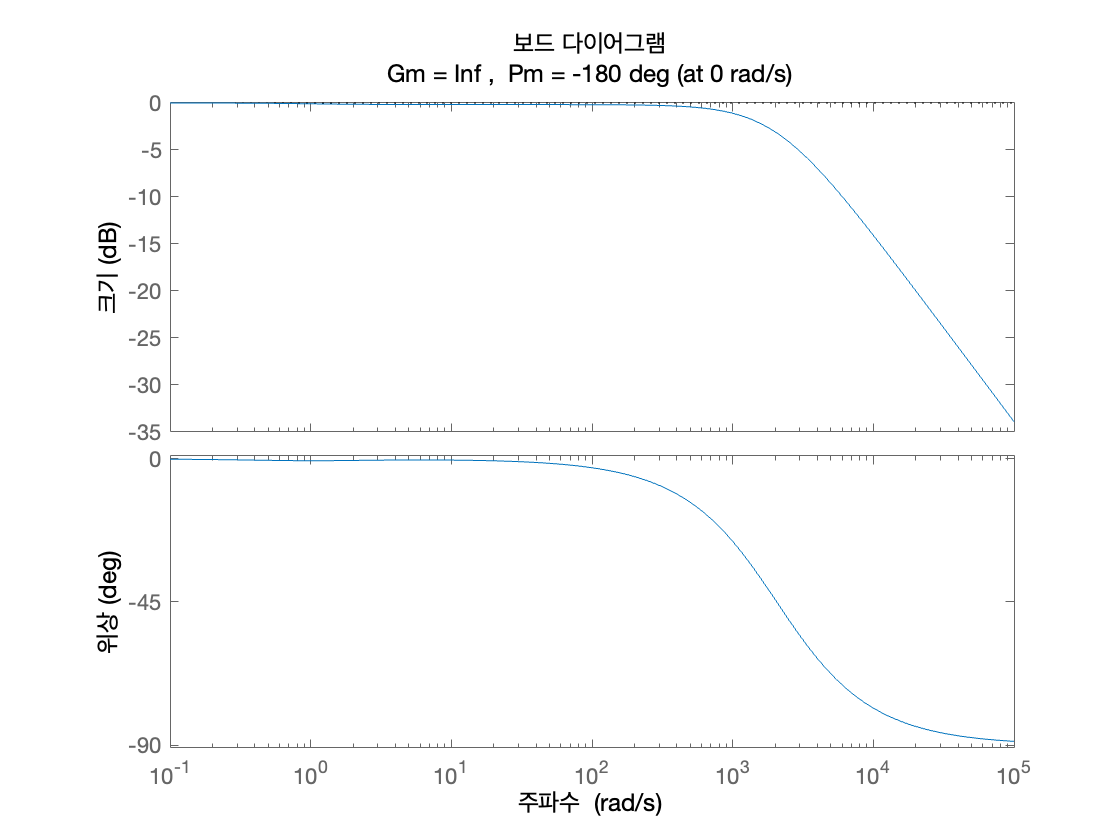

margin(sys)

ramp input을 봤을 때 입력 신호과 유사한 것을 볼 수 있다. 또한 bode plot에서도 phase margin이 180이상이므로 안정한 것을 볼 수 있다.